% 1.4.1

L=10000;

xi=5*rand(1,L)+1;
yi=6*rand(1,L)+2;

lgxi=sum(log10(xi));
lgyi=sum(log10(yi));

a1=floor(lgxi);
b1=10^(lgxi-a1);
a2=floor(lgyi);
b2=10^(lgyi-a2);

if a1<a2
    at=a1;bt=b1;
    a1=a2;b1=b2;
    a2=at;b2=bt;
end

a=a1;
b=b1+b2*10^(a2-a1);

if b>=10
    b=b/10;
    a=a+1;
end

fprintf('z = %f * 10 ^ %d\n',b,a);

% 1.4.2

x=1:1000;
k=1:9;
[X,K]=meshgrid(x,k);

pxk=X.^(K/2)./factorial(3*K);
px=sum(pxk,1);

figure()
plot(x,px);
xlabel('x');ylabel('p(x)');

% 1.4.3

k=1:9;
pk=1./factorial(3*k);
fprintf('p_k, k = 1~9\n',b,a);
fprintf('%e\n',pk);

% 1.4.4

N=1000;

x=1:N;
Fn=zeros(1,N);
an=zeros(1,order);

for ii=1:N
    lg=-ii*log(ii/exp(1))+sum(log(1:ii));
    Fn(ii)=1/sqrt(2*pi*ii)*exp(lg);
end

figure();
subplot(2,2,1);
plot(x,Fn);
xlabel('n');ylabel('F(n)');

F1n=(Fn-1).*x;
subplot(2,2,2);
plot(x,F1n);
xlabel('n');ylabel('F1(n)');

F2n=(F1n-1/12).*x;
subplot(2,2,3);
plot(x,F2n);
xlabel('n');ylabel('F2(n)');

F3n=(F2n-0.003472).*x;
subplot(2,2,4);
plot(x,F3n);
xlabel('n');ylabel('F3(n)');

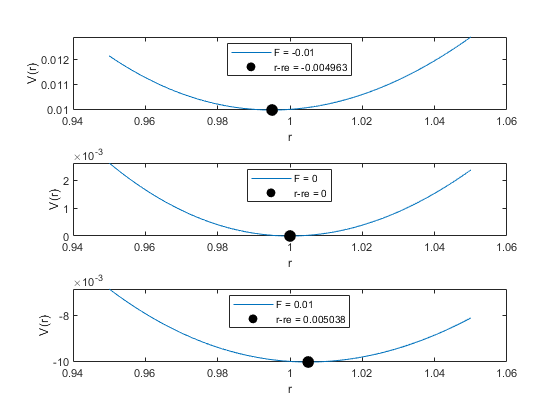

% 1.4.5

figure();
FF=[-.01 0 .01];

for ii=1:3
subplot(3,1,ii)
a=1;
re=1;
u=1;
F=FF(ii);

r=linspace(0.95,1.05,100001);

vr=u*(1-exp(-a*(r-re))).^2-F*r;
fd=find(vr==min(vr));

hold on;
plot(r,vr);
plot(r(fd),vr(fd),'k.','markersize',30);
hold off;
legend(['F = ' num2str(F)],['r-re = ' num2str(r(fd)-re)],'location','north');
box on;
xlabel('r');ylabel('V(r)');

end

syms a re u F r

vr=u*(1-exp(-a*(r-re))).^2-F*r

$$vr = u\,{\left({\mathrm{e}}^{-a\,\left(r-\mathrm{re}\right)}-1\right)}^{2}-F\,r$$


dvr=diff(vr,r)

$$dvr = -F-2\,a\,u\,{\mathrm{e}}^{-a\,\left(r-\mathrm{re}\right)}\,\left({\mathrm{e}}^{-a\,\left(r-\mathrm{re}\right)}-1\right)$$

syms x
y=1-sqrt(1-x);
y1=taylor(y,x,0,'Order',6)

$$y1 = \frac{7\,x^{5}}{256}+\frac{5\,x^{4}}{128}+\frac{x^{3}}{16}+\frac{x^{2}}{8}+\frac{x}{2}$$

x=[-.01 0 .01];
(1/2*x+3/8*x.^2+5/12*x.^3)*1000

ans =    -4.9629         0    5.0379
